% This code estimates the phase function from time series data.
% Author:
% Taichi Yamamoto
% yamamoto-taichi913@g.ecc.u-tokyo.ac.jp
% 
% If you use this code, please cite the following paper:
% Gaussian Process Phase Interpolation for estimating the asymptotic phase of a limit cycle oscillator from time series data
% Taichi Yamamoto, Hiroya Nakao, Ryota Kobatyashi
% Chaos, Solitons & Fractals, Volume 191, February 2025, 115913
% https://doi.org/10.1016/j.chaos.2024.115913

## presetting before running

clear;
close all;
set(0, "DefaultTextInterpreter", "latex")
%rng('default')

## Set oscillator and cycle data

% If you want to try other oscillators, 
% make another class similar to stuart_landau.m
% and write the equation and parameters there.
cla = stuart_landau();
dt = 0.005;
format long
% numerical T
% measure 1000 periods
tic;
[cla.T, cla.omega] = funcs.period(cla, 100, 1000);
toc

経過時間は 1.898142 秒です。


cla.T, cla.omega

ans =    6.283185000000000


ans =    1.000000048889152


% the origin of phase
cla.x_lc_0 = [1;0];
% exact cycle data for direct method
[x_lc, theta_lc] = funcs.phase_map(0,3,cla,1);
cla.x_lc = x_lc;
cla.scale = std(x_lc,0,2);

## True global phase function

[X,X1,X2,area_size] = utils.mesh_grid(cla);
%theta_cal = reshape(cla.phase_calc(X), area_size);
% numerical
M = 2000;
tic;
    [theta_map, invalid] = funcs.phase_numerical(X,x_lc,theta_lc,cla,M,1);
toc

経過時間は 1.447598 秒です。


theta_map = reshape(theta_map, area_size);
if sum(invalid)
    ini_invalid = X(:,invalid)
end

ini_invalid =      0
     0


## Data generation, Estimation by GPPI

data variables

% 4th slot is empty
omegas = zeros(1,4); scales = cell(1,4);
sin_models = cell(1,4); cos_models = cell(1,4); 
xs = cell(1,4); dxdts = cell(1,4); ns = zeros(1,4);
x_samples = cell(1,4);

settings

GPoptions = {"FitMethod", "PredictMethod", "BasisFunction",...
    "KernelFunction", "SigmaLowerBound";...
    "exact", "exact", "none", "matern52", 0.1};
M = 500;
% three noise levels
etas = [0.005, 0.01, 0.05];
time = M*dt

time =    2.500000000000000


format long
n = 100;
% test three noise levels
for i=1:3
    eta = etas(i);
    windowsize = 15;
    rng(0)
    % Phase on LC
    fprintf("eta: %8f, estimating omega",eta);
    tic;
    [T_noise, omega_noise] = funcs.period_noise(eta, windowsize, cla, 10, 1000);
    [~,~,x_lc_noise,theta_lc_noise] = funcs.phase_map(eta,windowsize,cla,omega_noise);
    n_lc = size(x_lc_noise,2);
    scale_noise = std(x_lc_noise,0,2);
    omegas(i) = omega_noise; scales{i} = scale_noise;
    fprintf("omega: %8f",omega_noise);
    toc
    
    % data genaration
    tic;
    fprintf("generating %d orbit data", n);
    rng(0)
    ini = utils.gen_initials(cla,n*3);
    [x,dxdt,x_data] = utils.gen_data(eta,M,ini,windowsize,dt,cla);
    [x_valid,theta_data,valid] = funcs.phase_data(x,cla,x_lc_noise,theta_lc_noise,scale_noise,1,0.001);
    x_valid = x_valid(:,:,1:n); theta_data = theta_data(:,1:n);
    m = size(x_valid, 2); ns(i) = size(x_valid,3);
    
    x_valid = x_valid(:,:);
    theta_data = theta_data(:);
    dxdt_valid = dxdt(:,:,valid); dxdt_valid = dxdt_valid(:,:,1:n);
    xs{i} = x_valid; dxdts{i} = dxdt_valid;
    fprintf("Full data: %d orbits, %d points", ns(i), size(x_valid,2))
    toc
    
    % GP sampling and learning
    tic;
    index = zeros(m,ns(i)); index(1:50:m,:) = 1;
    index = logical(index(:));
    x_sample = x_valid(:,index);
    theta_sample = theta_data(index);
    
    n_sample = size(x_sample,2);
    x_samples{i} = x_sample;
    fprintf("GP learning data: %d orbit %d points", ns(i), n_sample)
    [sin_models{i},cos_models{i}] = funcs.learn_GP(x_sample,theta_sample,scale_noise,GPoptions);
    fprintf("GP learning done")
    toc
end

eta: 0.005000, estimating omega

omega: 1.000000

経過時間は 9.171042 秒です。


generating 100 orbit data

Full data: 100 orbits, 48600 points

経過時間は 7.899544 秒です。


GP learning data: 100 orbit 1000 points

GP learning done

経過時間は 4.596168 秒です。


eta: 0.010000, estimating omega

omega: 1.000000

経過時間は 9.342667 秒です。


generating 100 orbit data

Full data: 100 orbits, 48600 points

経過時間は 3.580256 秒です。


GP learning data: 100 orbit 1000 points

GP learning done

経過時間は 2.156249 秒です。


eta: 0.050000, estimating omega

omega: 1.000002

経過時間は 8.994416 秒です。


generating 100 orbit data

Full data: 100 orbits, 48600 points

経過時間は 3.610377 秒です。


GP learning data: 100 orbit 1000 points

GP learning done

経過時間は 2.153978 秒です。


% Phase estimation on grid points
theta_hats = cell(1,4);
for i=1:3
    theta_hats{i} = reshape(funcs.phase_GP(X,sin_models{i},cos_models{i},scales{i}), area_size);
end

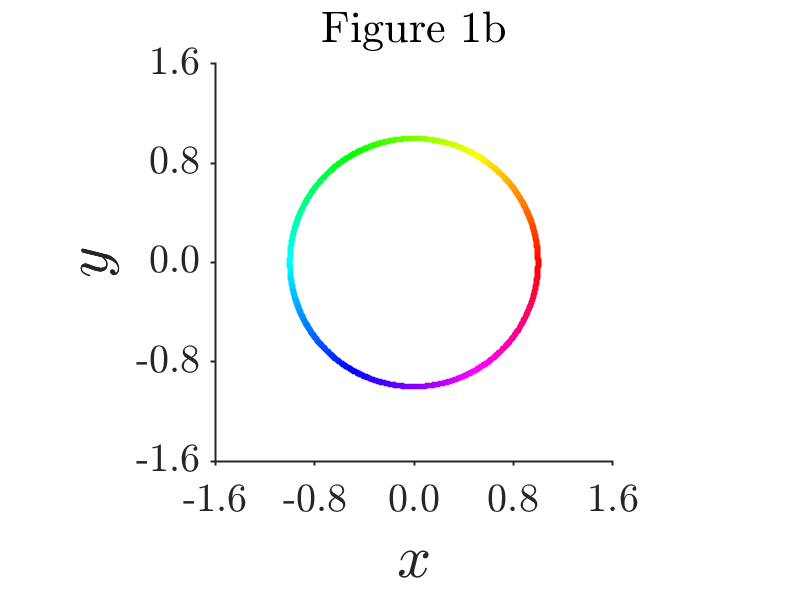

% Figure 1
% Phase on LC
tmp = ceil(128*theta_lc/pi); tmp(1) = 1;
color = hsv(256); color = color(tmp,:);
utils.fig_data(cla,x_lc,10,color,"Figure 1b",0);

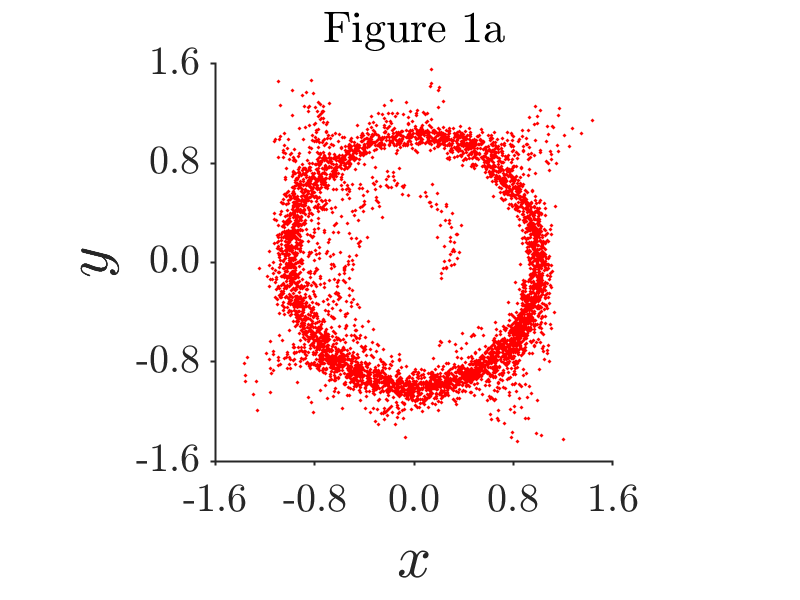

% (Partial) data points and their phase
tmp = 1:5:486*50;
x_show = x_valid(:, tmp);
theta_show = theta_data(tmp);
color = hsv(256); color = color(ceil(128*theta_show/pi),:);
utils.fig_data(cla,x_show,5,"r","Figure 1a",0);

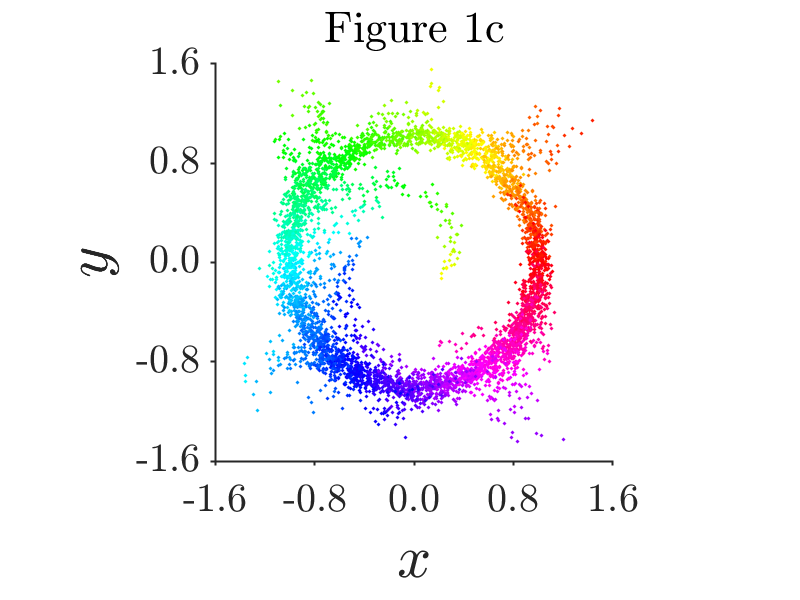

utils.fig_data(cla,x_show,5,color,"Figure 1c",0);

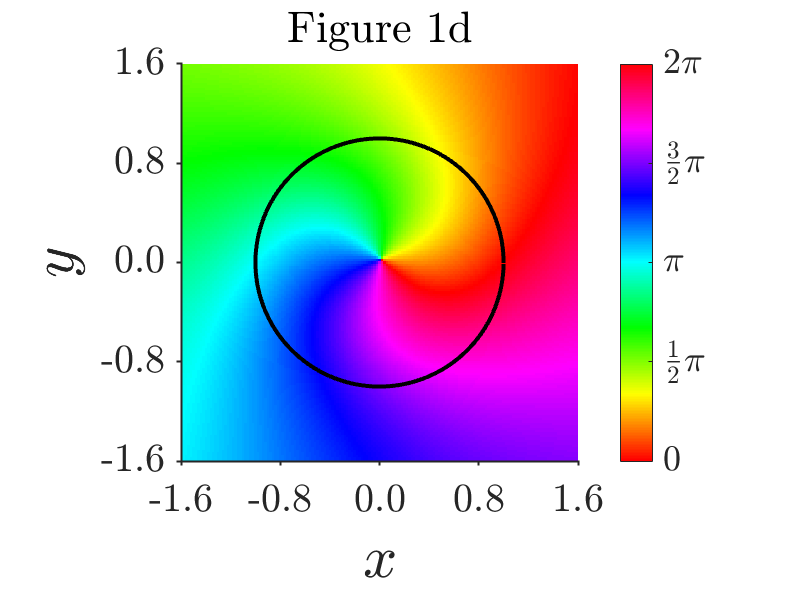

% Estimated phase function
utils.fig_phase_heat(cla,theta_hats{1},"Figure 1d");

% You can see the fitted GP kernel parameters by this
model = sin_models{1};
model.Sigma

ans =    0.100000067074697


model.KernelInformation.KernelParameterNames

ans = 2×1 の cell 配列
    {'SigmaL'}
    {'SigmaF'}


model.KernelInformation.KernelParameters

ans =    1.972126347826157
   0.706465782864535


## Estimation by DPR method

% If you use this code, please cite the following paper:
% Estimating asymptotic phase and amplitude functions of limit-cycle oscillators from time series data
% Norihisa Namura, Shohei Takata, Katsunori Yamaguchi, Ryota Kobayashi, and Hiroya Nakao
% Phys. Rev. E 106, 014204 – Published 7 July 2022
% https://doi.org/10.1103/PhysRevE.106.014204
tic;
gamma = 0;
p_phase = 18;
DPR_models = cell(1,4);
theta_hats2 = cell(1,4);
% apply DPR method to the same data (xs{i}, dxdts{i}, omegas(i))
for i=1:3
    [z1,z2,mu,sig] = learn.learn_phase(xs{i},dxdts{i},x_lc(:,1),omegas(i),p_phase,gamma);
    DPR_models{i} = {z1,z2,mu,sig};
    % estimate the phase on grid points
    theta_hats2{i} = reshape(learn.phase_model(X,z1,z2,p_phase,mu,sig), area_size);
end

 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0    2.820935e+02   7.487476e-12   8.102462e-06     0.000000e+00  
    1    2.820935e+02   9.964252e-15   6.297661e-06     0.000000e+00  

制約を満たす最小値が見つかりました。

目的関数が最適性の許容誤差値の範囲内の実行可能な方向
において非減少であり、制約が制約の許容誤差値の範囲内で
満たされているため、最適化は完了しました。

<停止条件の詳細>

 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0    9.014625e+02   1.513158e-12   1.583660e-05     0.000000e+00

toc

経過時間は 5.898064 秒です。


## Plot phase map

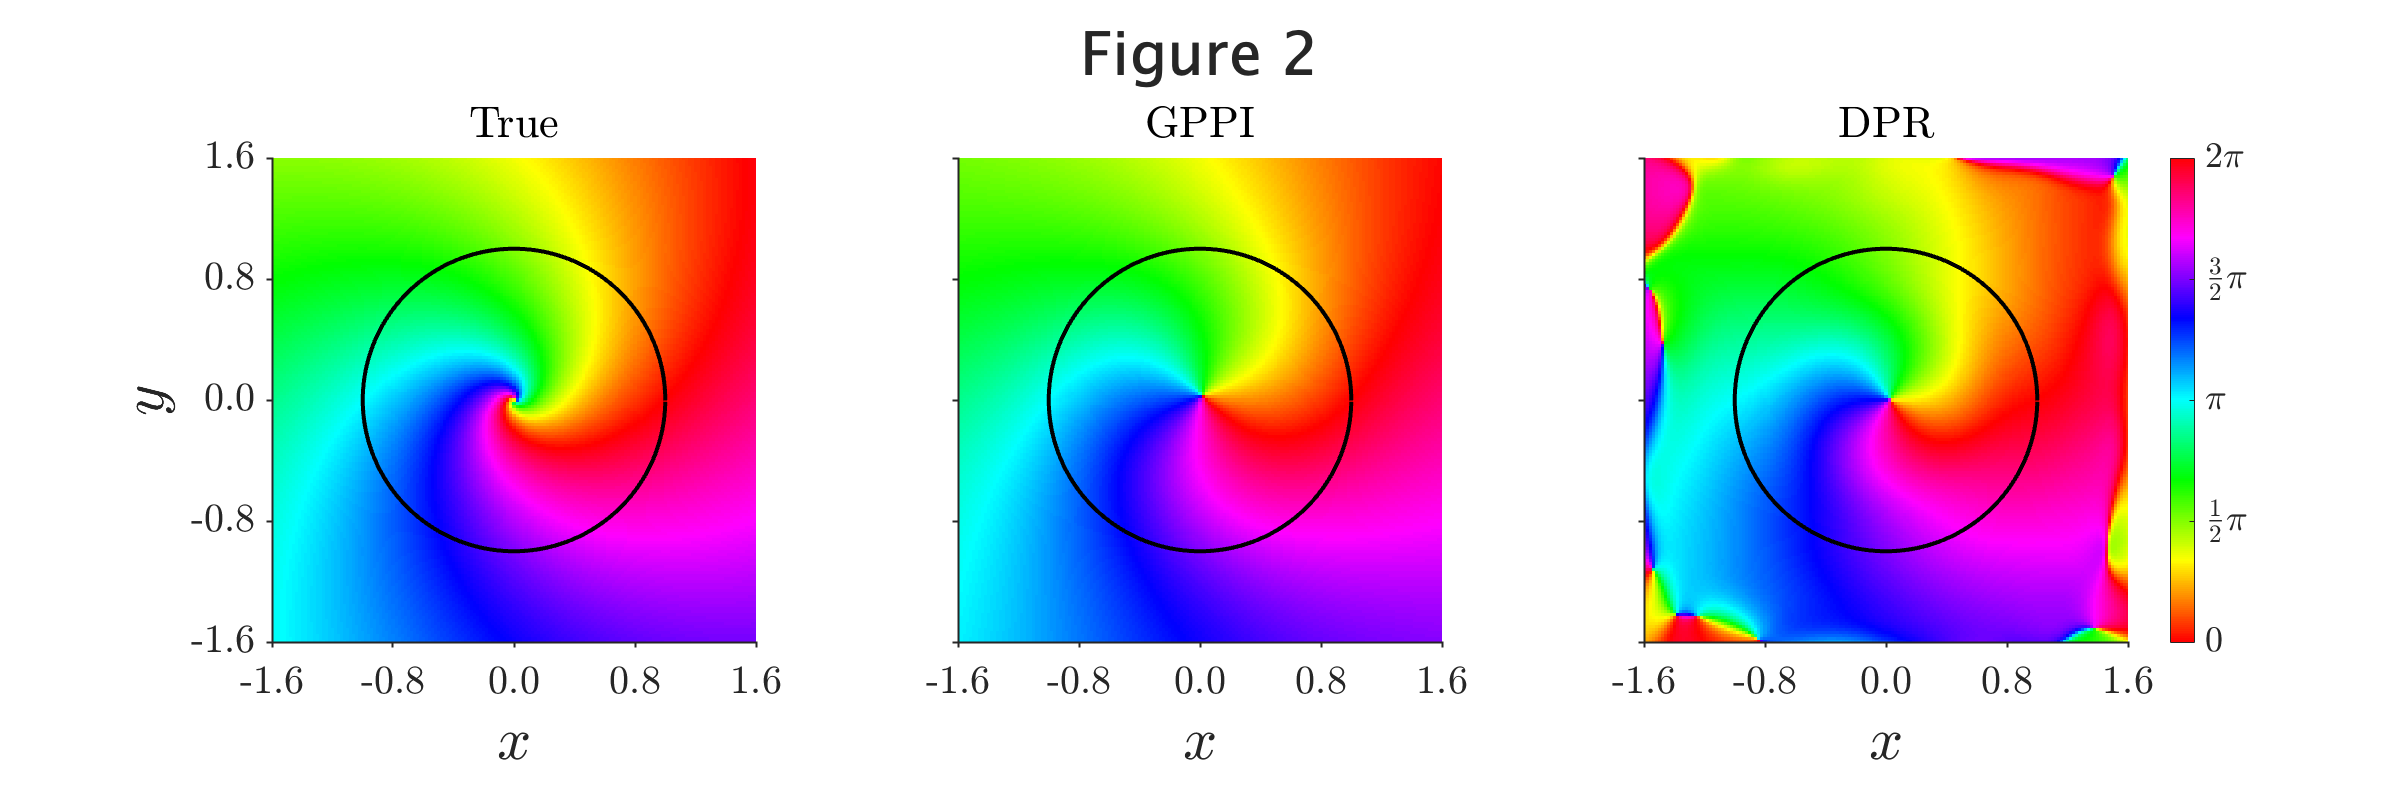

% Figure 2
fig = figure(); fig.Position(3:4) = [1200,400];
tiles = tiledlayout(1,3,"TileSpacing","tight");
title(tiles, "Figure 2", fontsize=30)
i=1;
thetas = {theta_map, theta_hats{i}, theta_hats2{i}};
names = ["True", "GPPI", "DPR"];
% plot phase
for i = 1:3
    nexttile(i); hold on
    colormap(gca,"hsv")
    imagesc("XData",cla.x_lim, "YData",cla.y_lim, "CData",thetas{i})
    ind = cla.plot_ind;
    plot(x_lc(ind(1),:),x_lc(ind(2),:),"k","LineWidth",2);
    hold off
    clim([0,2*pi]);
    axis equal
    xticks(cla.x_tick); xlim(cla.x_lim);
    yticks(cla.y_tick); ylim(cla.y_lim);
    xticklabels(""); yticklabels("")
    t = title(names(i)); t.FontSize = 20;
    ax = gca; ax.FontSize = 20;
    ax.TickLabelInterpreter = "latex";
    ax.TickDir = "out";
    ax.Layer = "top";
    ax.Box = "off"; ax.LineWidth = 1;
end
%colorbar
for i=3
    nexttile(i)
    colorbar('Ticks',[0,pi/2,pi,3*pi/2,2*pi],...
    'TickLabels',["$0$","$\frac{1}{2}\pi$","$\pi$","$\frac{3}{2}\pi$","$2\pi$"],...
    TickLabelInterpreter='latex');
end

% xlabel
for i=1:3
    nexttile(i)
    t = xlabel(cla.x_name, Interpreter="latex"); t.FontSize = 30;
    xticklabels(compose("%.1f", cla.x_tick));
end

% ylabel
for i=[1]
    nexttile(i)
    t = ylabel(cla.y_name, Interpreter="latex"); t.FontSize = 30;
    yticklabels(compose("%.1f", cla.y_tick));
end
set(gcf,"visible","on");

% Figure 8a
fig = figure(); fig.Position(3:4) = [900,800];
tiles = tiledlayout(2,2,"TileSpacing","tight");
title(tiles, "Figure 8a", fontsize=30)
i=1;
thetas = {theta_hats{i}, theta_hats2{i}};
names = ["GPPI", "DPR"];
% reduce too many data points for scatter plots
datas = {x_samples{i}, utils.reduce_data(xs{i},x_lc,scales{i},5e-4,1e-4,3)};

data reduced: 48600 -> 10832

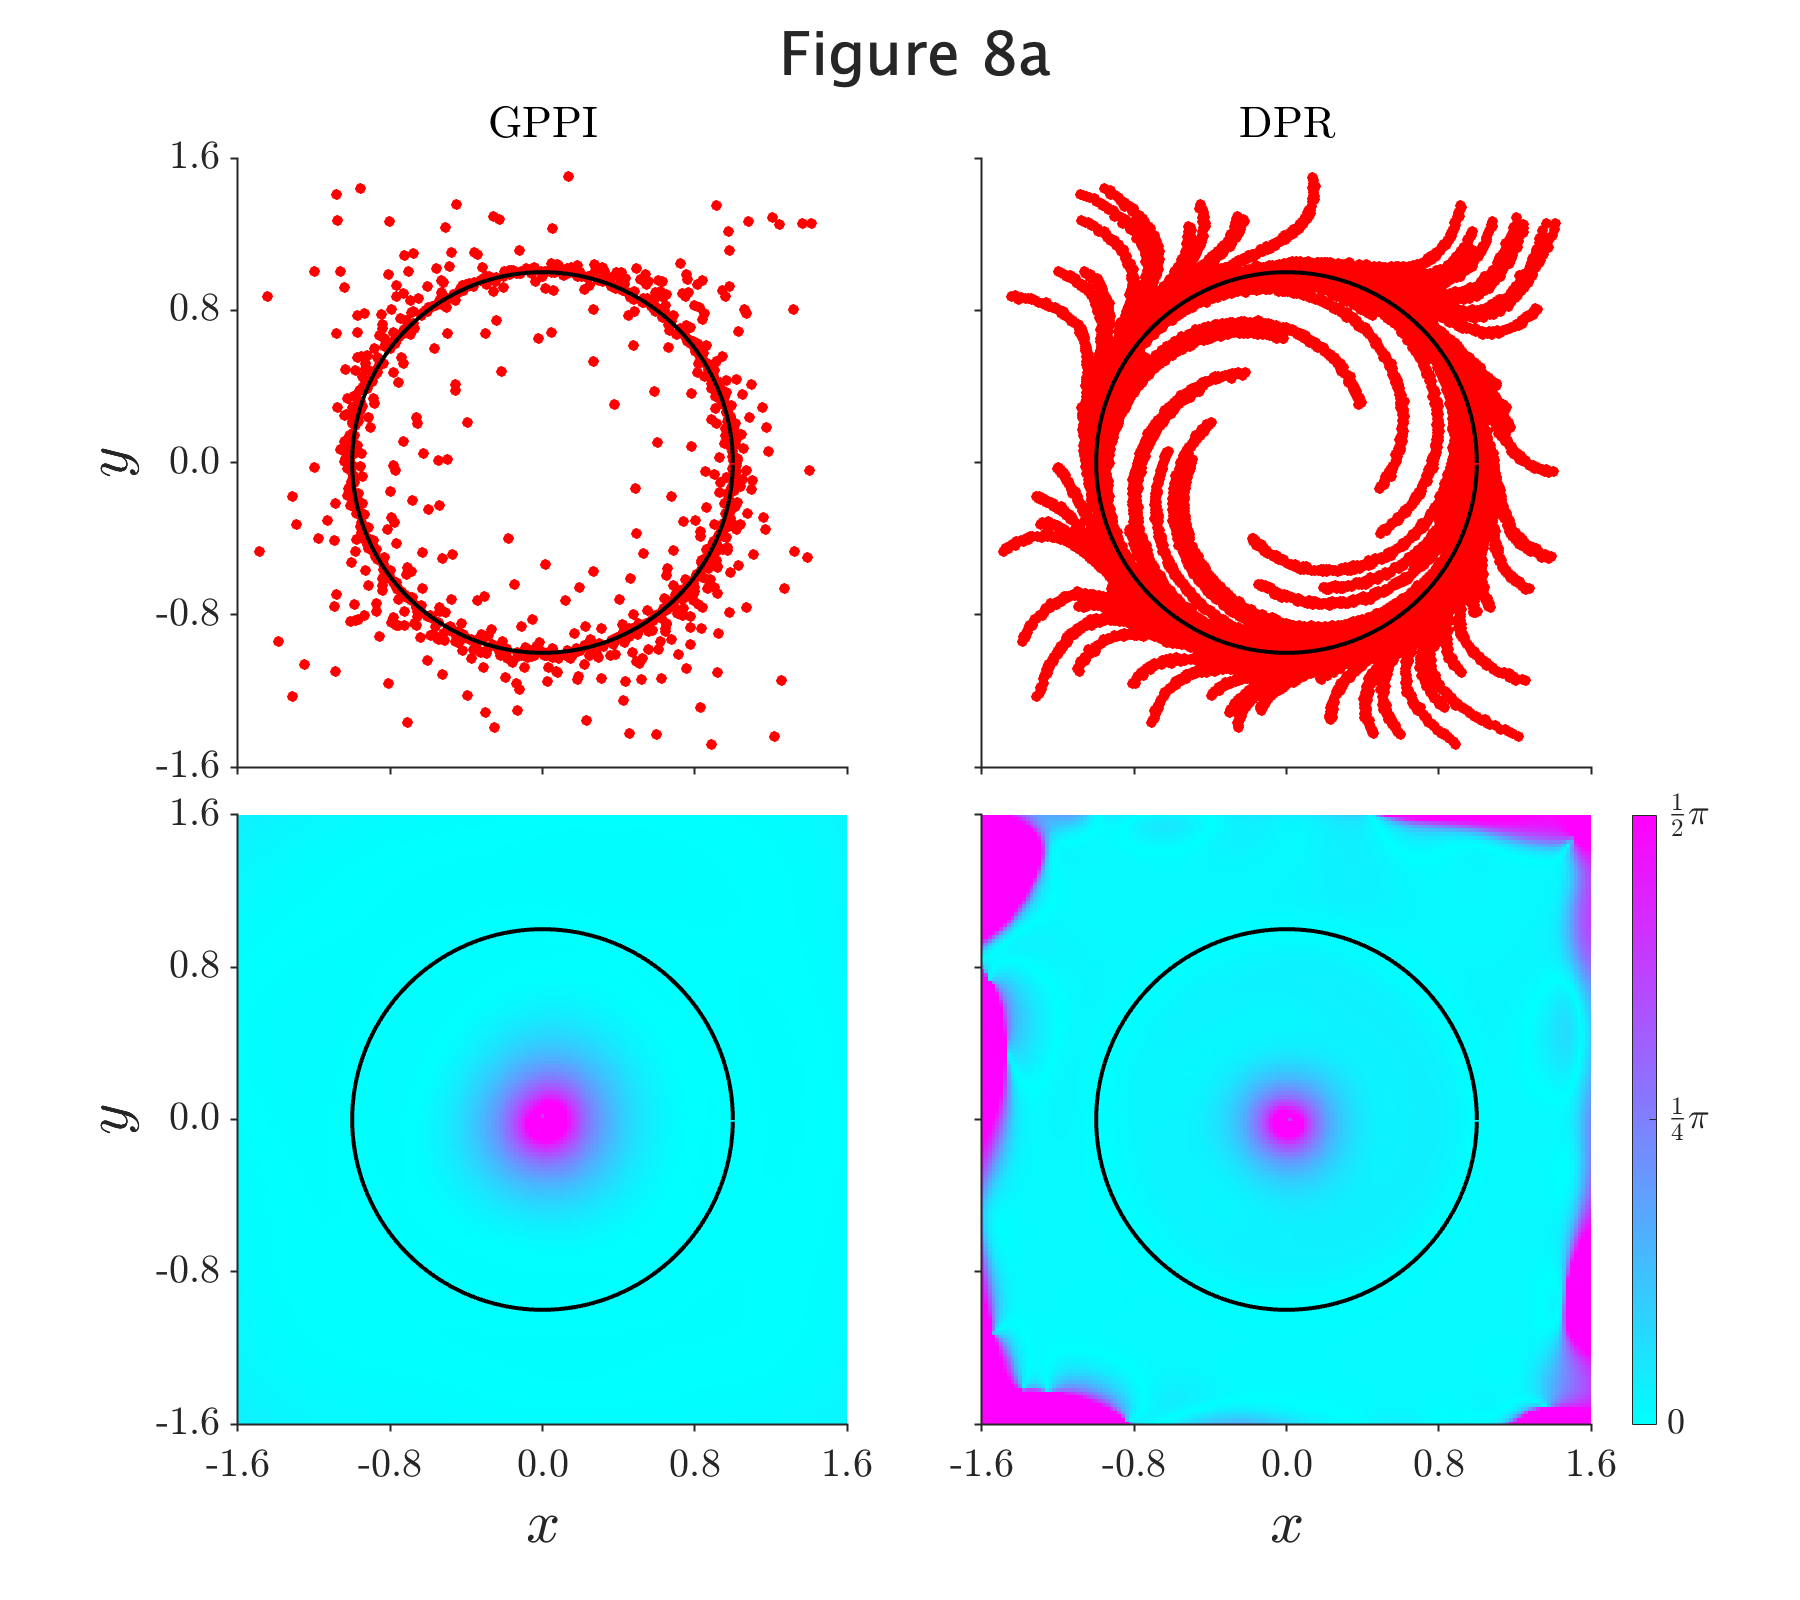

% non-reduced ver.
%datas = {x_samples{i}, xs{i}};

ind = cla.plot_ind;
% plot data
for i = 1:2
    nexttile(i); hold on
    scatter(datas{i}(ind(1),:),datas{i}(ind(2),:),30,"r","filled");
    plot(x_lc(ind(1),:),x_lc(ind(2),:),"k","LineWidth",2);
    hold off
    t = title(names(i)); t.FontSize = 20;
end

% plot errors
for i = 1:2
    nexttile(i+2); hold on
    diff = thetas{i} - theta_map;
    tmp = diff(:);
    tmp = funcs.theta_adjust(tmp);
    tmp = reshape(abs(tmp), size(diff));
    colormap(gca,cool)
    imagesc("XData",cla.x_lim, "YData",cla.y_lim, "CData",tmp)
    plot(x_lc(ind(1),:),x_lc(ind(2),:),"k","LineWidth",2);
    clim([0,pi/2]);
    hold off
end

% axes
for i=1:4
    nexttile(i);
    axis equal
    xticks(cla.x_tick); xlim(cla.x_lim);
    yticks(cla.y_tick); ylim(cla.y_lim);
    xticklabels(""); yticklabels("")
    ax = gca; ax.FontSize = 20;
    ax.TickLabelInterpreter = "latex";
    ax.TickDir = "out";
    ax.Layer = "top";
    ax.Box = "off"; ax.LineWidth = 1;
end

%colorbar (error)
for i=4
    nexttile(i)
    colorbar('Ticks',[0,pi/4,pi/2],...
    'TickLabels',["$0$","$\frac{1}{4}\pi$","$\frac{1}{2}\pi$"],...
    TickLabelInterpreter='latex');
end

% xlabel
for i=3:4
    nexttile(i)
    t = xlabel(cla.x_name, Interpreter="latex"); t.FontSize = 30;
    xticklabels(compose("%.1f", cla.x_tick));
end
% ylabel
for i=[1,3]
    nexttile(i)
    t = ylabel(cla.y_name, Interpreter="latex"); t.FontSize = 30;
    yticklabels(compose("%.1f", cla.y_tick));
end

set(gcf,"visible","on");

## nPRF calculation

% define pulses to 4 directions (x+, y+, x-, y-)
pulse = zeros(2,4); pulse_i = zeros(1,4);
varsigma = 0.2;
tic
for j=1:4
    c = j; if c>2 c = j-2; end
    sign = 1; if j>2 sign = -1; end
    pulse_i(j) = sign * varsigma;
    pulse(c,j) = sign * varsigma;
end
pulse

pulse =    0.200000000000000                   0  -0.200000000000000                   0
                   0   0.200000000000000                   0  -0.200000000000000


% analytical calculation
G = zeros(n_lc,4);
theta_lc_calc = cla.phase_calc(x_lc);
for j=1:4 % for each pulse direction
    x_impulse = x_lc + pulse(:,j);
    phi = cla.phase_calc(x_impulse);
    G(:,j) = funcs.theta_adjust(phi - theta_lc_calc) / pulse_i(j);
end
toc

経過時間は 0.033676 秒です。


% numerical calculation
tic
for j=1:4
    x_impulse = x_lc + pulse(:,j);
    [phi,invalid] = funcs.phase_numerical(x_impulse,x_lc,theta_lc,cla,2000,1);
    if sum(invalid)% if not converged to cycle
        pulse(:,j)
        x_impulse(:,invalid)
    end
    G(:,j) = funcs.theta_adjust(phi - theta_lc) / pulse_i(j);
end
toc;

経過時間は 0.352015 秒です。


## nPRF estimation (by GPPI and DPR)

% GPPI
g_hats = cell(1,4);
tic
for i=1:3 % for each data (noise levels)
    g_hat = zeros(n_lc,4);
    for j=1:4 % for each pulse direction
        x_impulse = x_lc + pulse(:,j);
        phi = funcs.phase_GP(x_impulse,sin_models{i},cos_models{i},scales{i});
        g_hat(:,j) = funcs.theta_adjust(phi - theta_lc(:)) / pulse_i(j);
    end
    g_hats{i} = g_hat;
end
toc;

経過時間は 0.465768 秒です。


% DPR
g_hats2 = cell(1,4);
tic
for i=1:3
    g_hat = zeros(n_lc,4);
    tmp = DPR_models{i};
    [z1,z2,mu,sig] = tmp{:};
    for j=1:4
        x_impulse = x_lc + pulse(:,j);
        phi = learn.phase_model(x_impulse,z1,z2,p_phase,mu,sig);
        g_hat(:,j) = funcs.theta_adjust(phi - theta_lc(:)) / pulse_i(j);
    end
    g_hats2{i} = g_hat;
end
toc;

経過時間は 0.234043 秒です。


% Table 1
A = zeros(5,6);
for i=1:3
    for j=1:4
        A(j,i*2) = funcs.coefficient_determination(G(:,j), g_hats2{i}(:,j));
        A(j,i*2-1) = funcs.coefficient_determination(G(:,j), g_hats{i}(:,j));
    end
end
A(5,:) = sum(A(1:4,:),1)/4;
format short
notes = ["x+","y+","x-","y-"];
tmp = table(A(:,1),A(:,2),A(:,3),A(:,4),A(:,5),A(:,6), ...
    RowNames=[notes,"Avg."], ...
    VariableNames=["GPPI1", "DPR1", "GPPI2", "DPR2", "GPPI10", "DPR10"])

tmp = 5×6 table
             GPPI1      DPR1       GPPI2      DPR2      GPPI10      DPR10  
            _______    _______    _______    _______    _______    ________

    x+      0.99786    0.96145    0.99813    0.87442    0.97027    -0.12154
    y+       0.9988    0.94561    0.99859     0.8264    0.98603     0.83152
    x-      0.99879     0.9382    0.99872    0.78851    0.97122    -0.96002
    y-      0.99873     0.9535    0.99886    0.83857    0.98355     -1.7879
    Avg.    0.99855    0.94969    0.99857    0.83198    0.97777    -0.50949


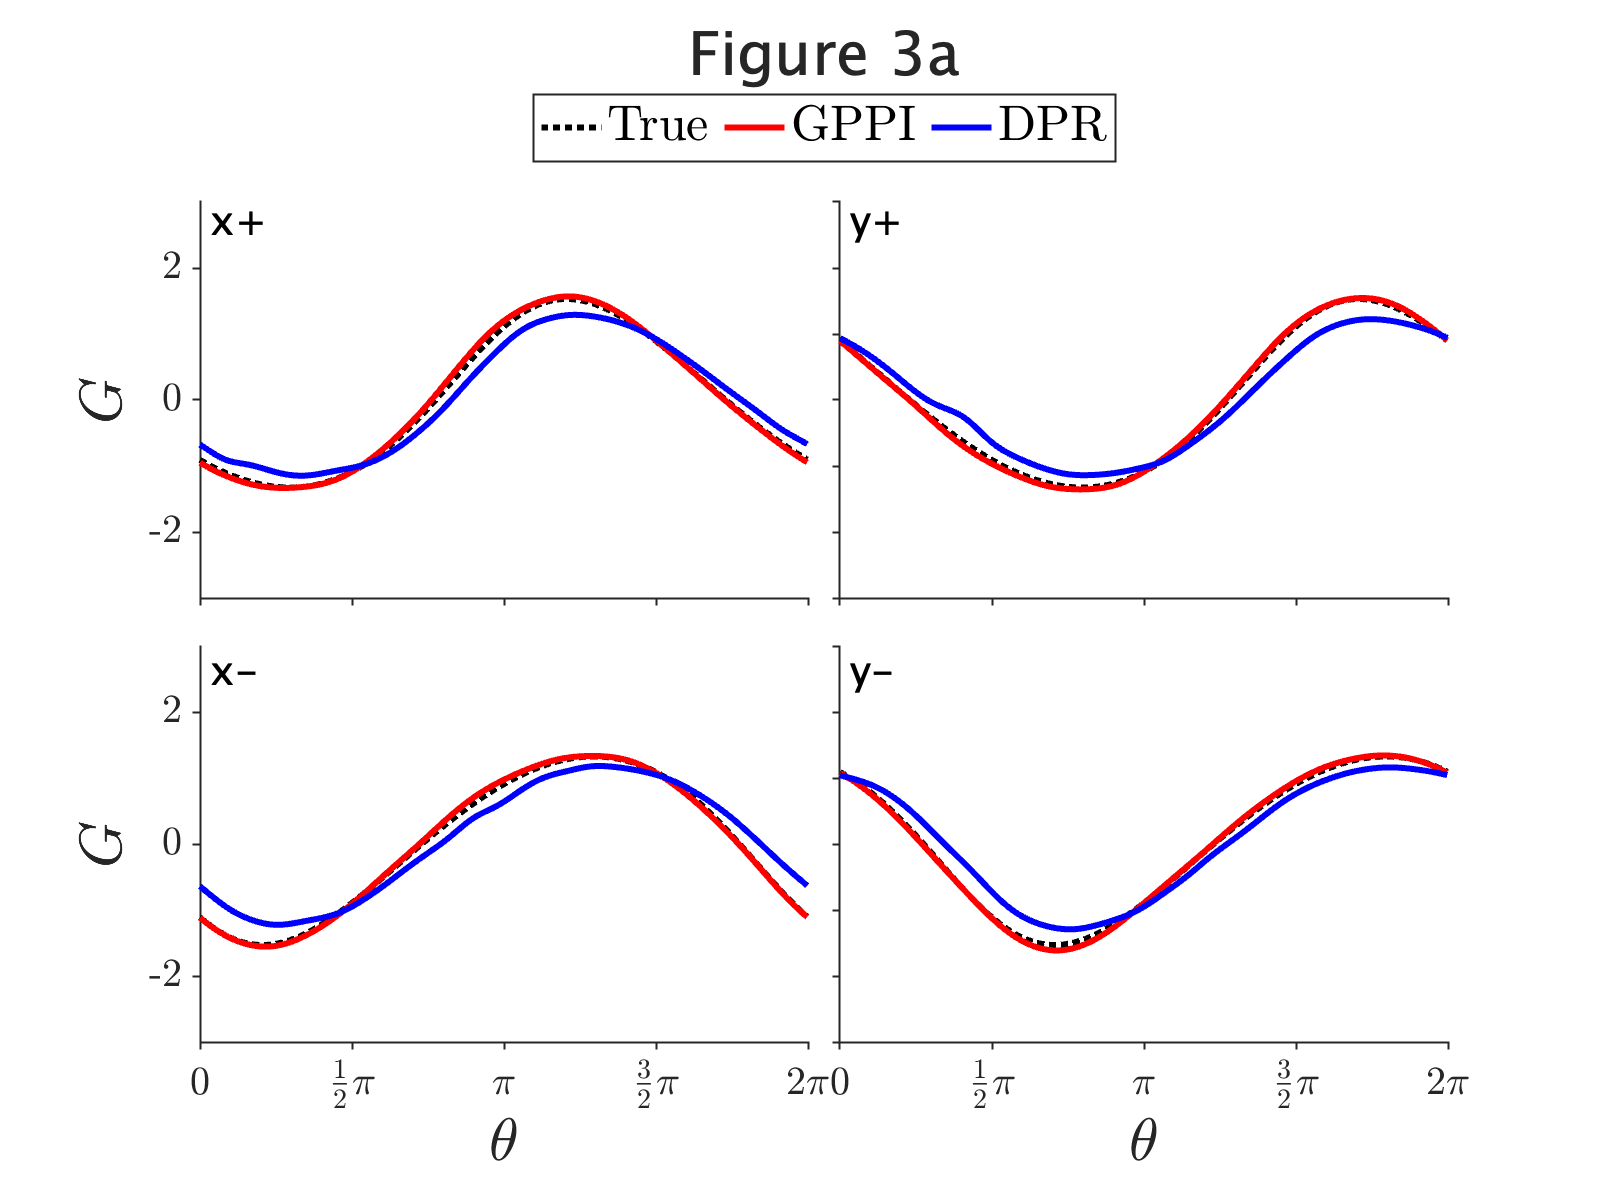

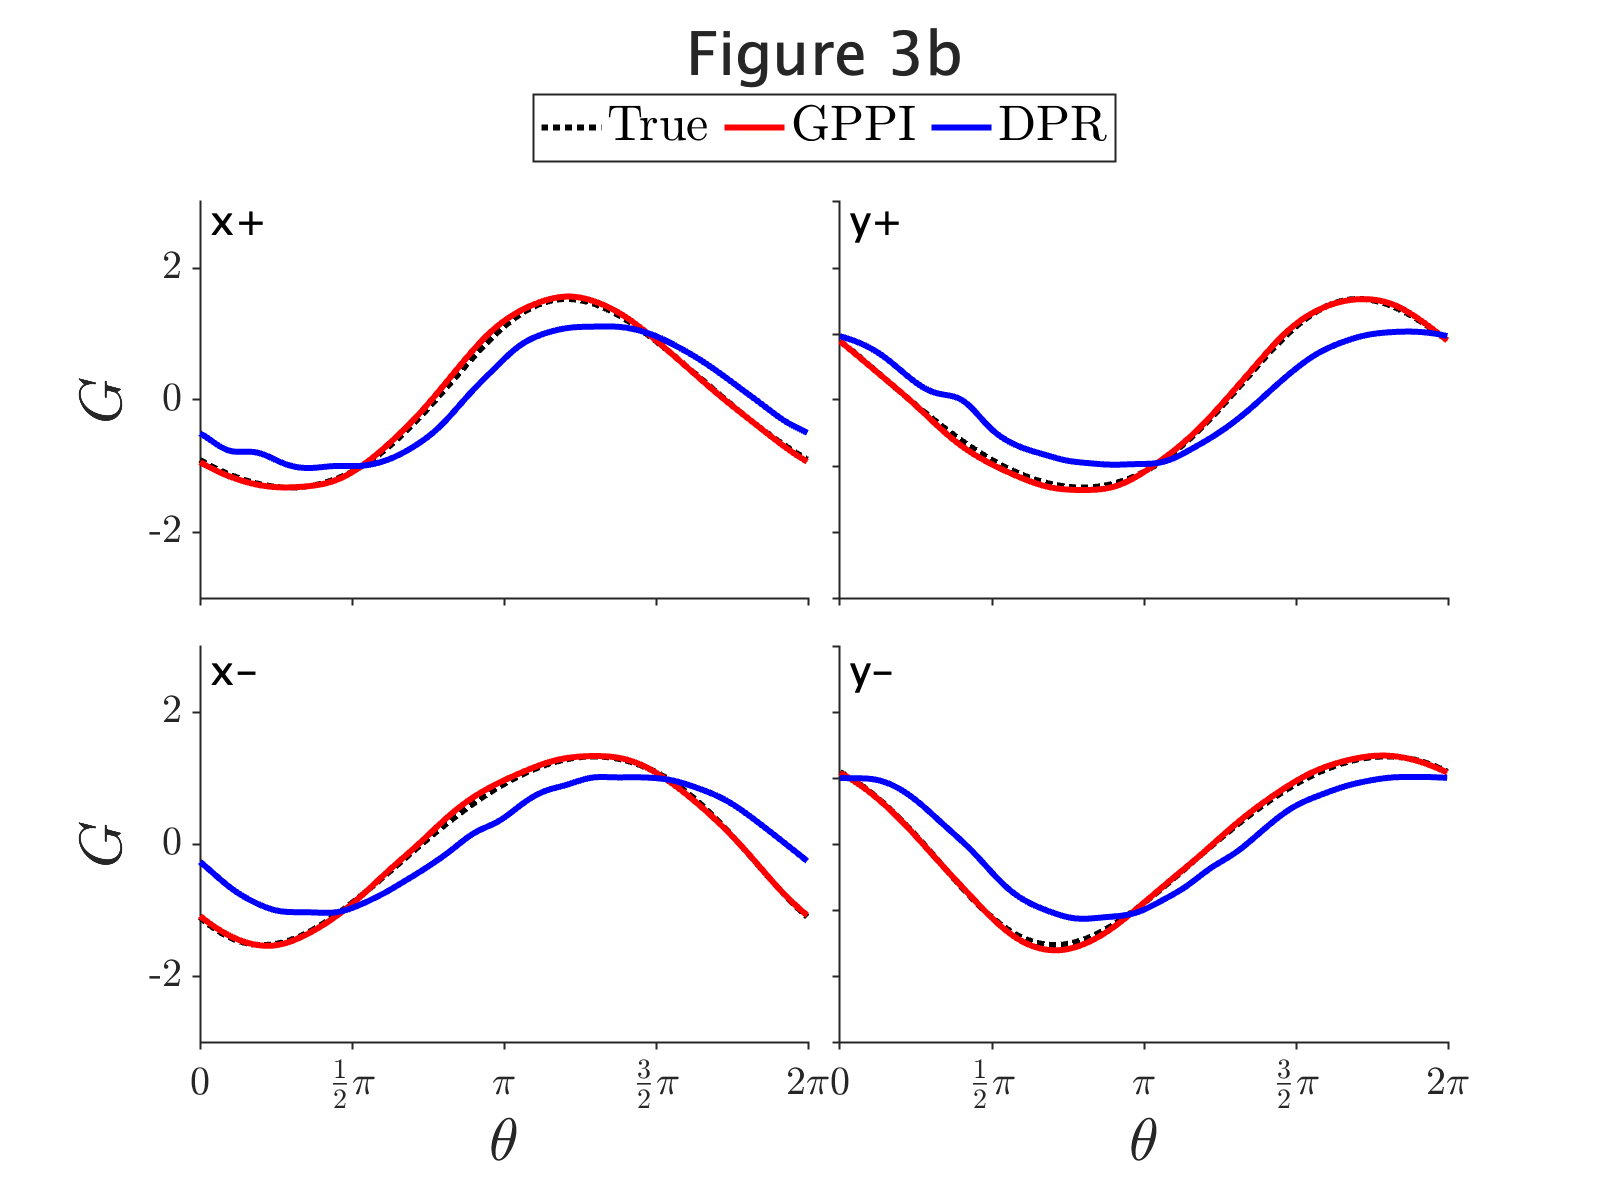

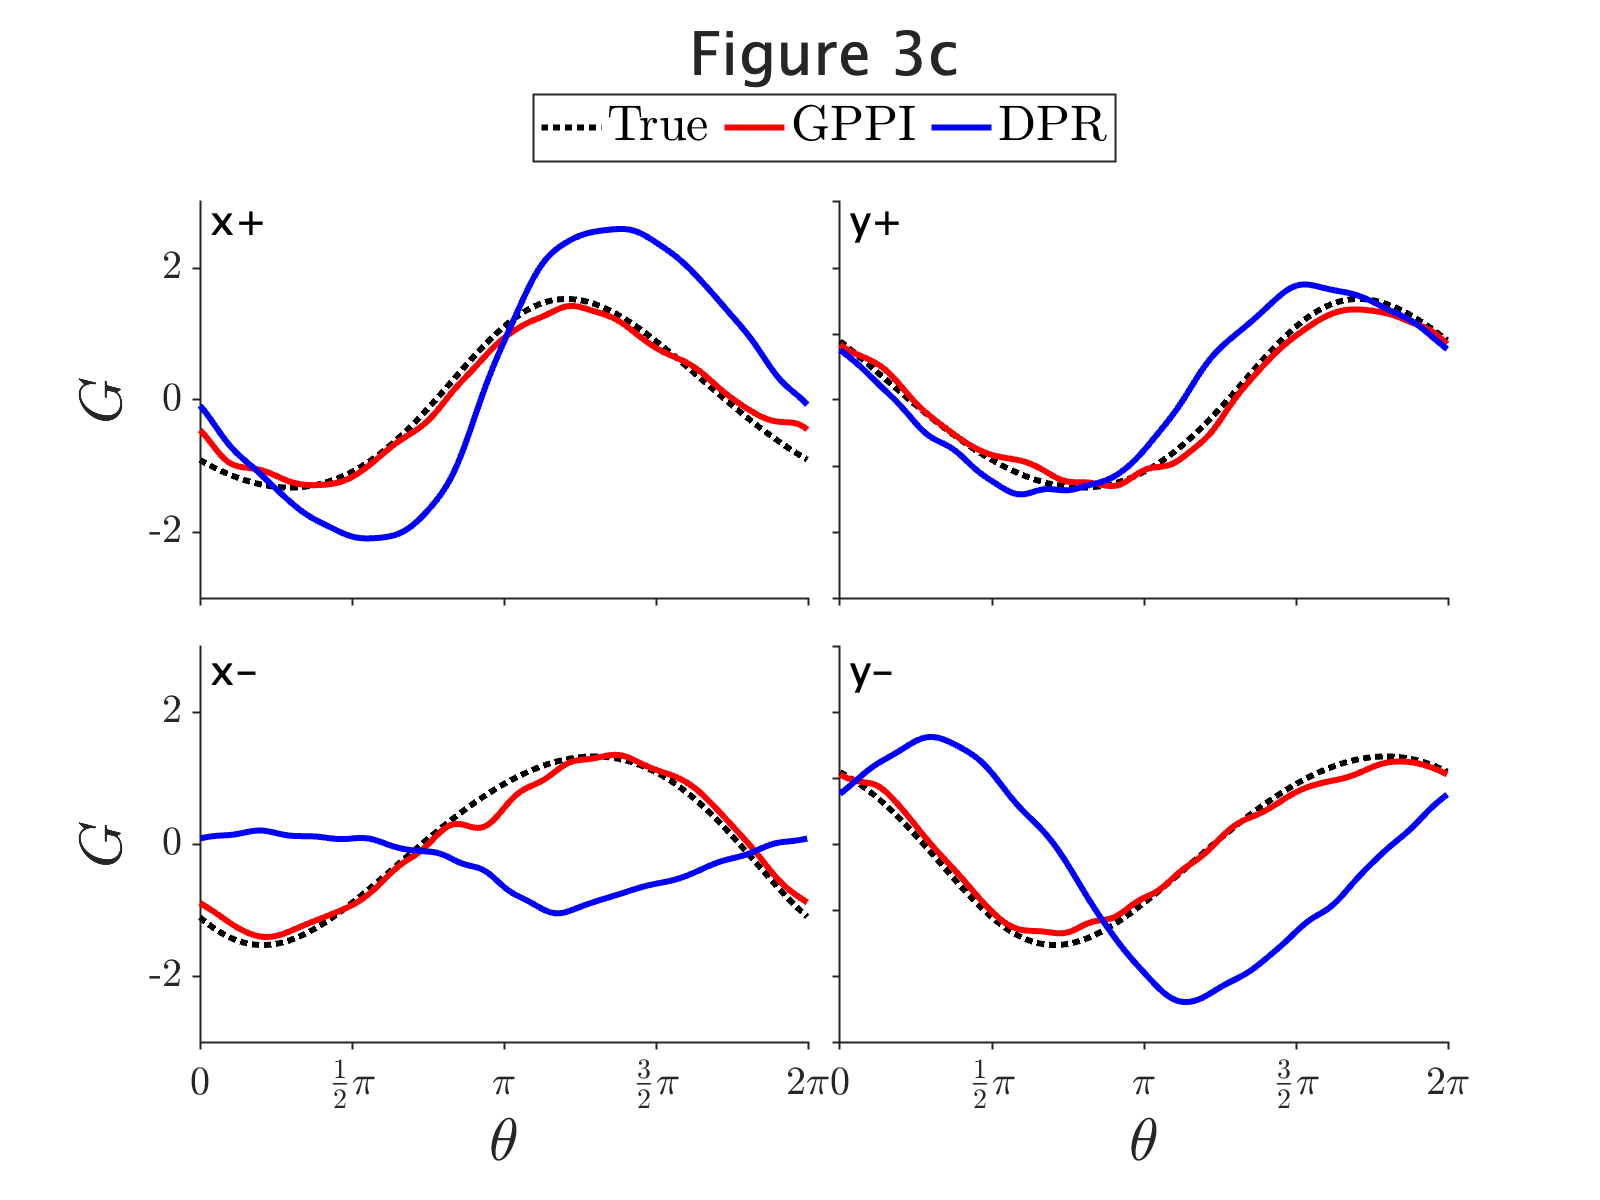

%Figure 3
titles = ["Figure 3a", "Figure 3b", "Figure 3c"];
for i = 1:3 % for each data (noise levels)
    fig = figure(); fig.Position(3:4) = [800,600];
    tiles = tiledlayout(2,2,"TileSpacing","tight");
    title(tiles, titles(i), fontsize=30)
    % for each panel (pulse direction)
    for j=1:4
        nexttile(j);
        prc = G(:,j);
        prc_hat = g_hats{i}(:,j);
        prc_hat2 = g_hats2{i}(:,j);
        hold on
        plot(theta_lc,prc,':k','LineWidth',3)
        plot(theta_lc,prc_hat,'r','LineWidth',3)
        plot(theta_lc,prc_hat2,'b','LineWidth',3)
        ax = gca; ax.FontSize = 20;
        ax.TickLabelInterpreter = "latex";
        ax.LabelFontSizeMultiplier = 1.5;
        ax.Box = "off"; ax.LineWidth = 1;
        ax.TickDir = "out";
        xlim([0,2*pi])
        xticks([0,pi/2,pi,3*pi/2,2*pi])
        xticklabels("")
        ylim([-3,3]);
    end
    % legend
    nexttile(1);
    lgd = legend(); lgd.FontSize = 25;
    lgd.Interpreter = "latex";
    lgd.String = ["True", "GPPI", "DPR"];
    lgd.Orientation = "horizontal";
    lgd.Layout.Tile = 'north';
    % y label on left
    for j=[1,3]
        nexttile(j); ylabel("$G$");
    end
    % remove y ticks on right panels
    for j=[2,4]
        nexttile(j); yticklabels("");
    end
    % insert x label and ticks on under panels
    for j=[3,4]
        nexttile(j); xlabel("$\theta$");
        xticklabels(["$0$","$\frac{1}{2}\pi$","$\pi$","$\frac{3}{2}\pi$","$2\pi$"]);
    end
    % insert notes for each panel
    notes = ["x+","y+","x-","y-"];
    for j=1:4
        nexttile(j);
        tmp = gca().Position; tmp = [tmp(1),tmp(2)+tmp(4)];
        tmp = annotation("textbox", [tmp(1), tmp(2)-0.05, 0.05, 0.05],"String",notes(j));
        tmp.EdgeColor = "none"; tmp.FontSize = 20;
    end
    set(gcf,"visible","on")
end